**Simulation des EDPs **

# Aplication du méthode des élements finis

TPs des jours 25/05 et 05/06/23

**Résolution d'un écoulement de Poiseuille**

**Déric Augusto FRANÇA DE SALES **

mail : deric-augusto.franca-de-sales6@etu.univ-lorraine.fr.

Codes produits dans la version R2020a du Simulink MATLAB en live script. 

Pour exécuter les codes de ce fichier, il faut également avoir recours aux fonctions auxiliaires : 

- Mailleur_Simple_Poiseuille_Rect.m

- Mailleur_Simple_Poiseuille_TriEqui.m

- Converti_Mailleur_Freefem.m

## Introduction

Dans cette pratique, nous traiterons de la résolution par éléments finis de type Pi/2D d'un écoulemnent de Poiseuille de liquides visqueur non newtoniens dans une conduite de section arbitraire. 

### la technique des éléments finis de type Pi/2D

La méthode des éléments finis de type Pi/2D est une technique numérique utilisée pour résoudre des problèmes de mécanique des fluides en deux dimensions (2D). Elle est basée sur la discrétisation du domaine en éléments finis triangulaires avec des fonctions d'interpolation spécifiques. Ces étapes sont les suivantes : 

1.** Discrétisation du domaine :** Le domaine d'étude est divisé en un maillage de triangles. Les sommets de ces triangles, appelés nœuds, servent de points de référence pour l'approximation des solutions;

2. **Définition des fonctions d'interpolation :** Des fonctions d'interpolation sont définies pour représenter les variations des paramètres du problème à l'intérieur de chaque élément fini. Dans le cas de la méthode Pi/2D, des fonctions d'interpolation de type Pi (fonctions polynomiales) sont utilisées pour décrire les champs de vitesse, de pression et d'autres grandeurs physiques;

3 . **Approximation des équations :** Les équations gouvernant le problème sont approximées en utilisant les fonctions d'interpolation définies précédemment. Cela permet de transformer les équations différentielles en un système d'équations algébriques, qui peut être résolu numériquement;

4. **Assemblage du système :** Les contributions de chaque élément fini au système d'équations global sont assemblées. Cela implique la combinaison des matrices de masse, de rigidité et de flux, ainsi que des vecteurs de charge, pour former le système d'équations global;

5. **Imposition des conditions aux limites :** Les conditions aux limites, telles que les conditions de Dirichlet (valeurs imposées) ou de Neumann (flux imposés), sont prises en compte en modifiant le système d'équations global. Cela permet de refléter les conditions physiques spécifiques du problème;

6. **Résolution du système :** Le système d'équations est résolu numériquement pour obtenir les valeurs des inconnues (par exemple, les champs de vitesse et de pression) à l'intérieur du domaine;

7. **Post-traitement : **Les résultats obtenus peuvent être visualisés et analysés pour étudier le comportement du fluide, tels que les profils de vitesse, les lignes de courant, les champs de pression, etc. Des quantités d'intérêt peuvent également être calculées, comme le débit volumique, les forces exercées sur les parois, etc.

La méthode des éléments finis de type Pi/2D est largement utilisée dans la résolution numérique des problèmes de mécanique des fluides en 2D, notamment pour les écoulements incompressibles et les écoulements turbulents. Elle permet d'obtenir des solutions précises et fiables en utilisant des ressources informatiques relativement abordables. Dans le cas de notre problème, nous traiterons d'un écoulement de Poiseuille.

### L'écoulement de Poiseuille

L'écoulement de Poiseuille, également connu sous le nom d'écoulement laminaire, décrit le mouvement d'un fluide visqueux à travers un tube cylindrique de longueur L et de rayon R, sous l'influence d'une différence de pression ΔP appliquée entre les extrémités du tube. Cet écoulement a été étudié par le physicien français Jean Léonard Marie Poiseuille au 19e siècle. 

L'écoulement de Poiseuille est régi par l'équation de Poiseuille, qui donne le débit volumique (Q) à travers le tube $Q = \frac{\pi \cdot \Delta P \cdot R^4}{8 \cdot \eta \cdot L}$, où $\Delta P$ est la différence de pression entre les extremités du tube, R le rayon du tube, $\eta$ la viscosité du fluide et L la longueur du tube. Cette équation montre que le débit volumique dépend du quatrième pouvoir du rayon du tube, ce qui signifie que de petites variations du rayon peuvent entraîner des changements significatifs dans le débit.

L'écoulement de Poiseuille est caractérisé par un profil de vitesse parabolique. Au centre du tube, la vitesse du fluide est maximale, tandis qu'elle est nulle au niveau des parois du tube en raison de la friction. Les couches de fluide adjacentes se déplacent à des vitesses différentes, formant ainsi des "couches" de fluide qui glissent les unes sur les autres.

La viscosité du fluide joue un rôle crucial dans cet écoulement. Un fluide plus visqueux aura une résistance plus élevée à l'écoulement, ce qui réduira le débit volumique. De plus, une augmentation de la longueur du tube ou une diminution de son rayon aura également pour effet de réduire le débit.

## Objectif

L'objectif de ce TP est de pratiquer la méthode des éléments finis et ses étapes. Nous essayons à la fin de trouver les figures correspondant à l'écoluement laminaire en testant les trois différents types de maillage proposés. 

## Création du maillage

Obs : Sauter cette partie si le maillage existe déjà. Sinon la fonction "Mailleur_Simple...." será crée, et aussi le fichier "NomfichMaillage", la fonction "Converti_Mailleur_Freefem" et le fichier "NomfichMaillage".

clear all; close all; clc;

Nous pouvons créer trois modèles de maillage triangulaires : en format carrées, triangulaires ou en forme de cacaouette :

- 0 carré       

- 1 triangle  

- 2 cacaouette 

### **Coordonnées du maillage **

Il existe deux systèmes de coordonnées concurrents dans le maillage pour les sommets du triangle. Le premier est une numérotation pour chaque nœud du maillage. Le second est un index local qui numérote les sommets de chaque triangle. Ainsi, chaque triangle aura des sommets 1, 2 et 3 qui correspondront chacun à un numéro de sommet dans le maillage. Il existe également un système de coordonnées pour chaque triangle. Ainsi, à chaque triangle du maillage correspond un numéro. 

### **Variables **

En choisissant le type de maillage en changeant la valeur de la variable mode, les fonctions externes sont exécutées afin de créer le maillage, et les variables suivantes sont créées :

- Nt $\rightarrow$ nombre de formes triangles dans le maillage

- Ns $\rightarrow$ nombre de sommets (tout les noeuds du maillage)

- N $\rightarrow$ nombre de sommets interieurs (sans considérer les noeuds du bord du maillage)

- Num $\rightarrow$ table de conectivité (est une matrice dont le premier élément est le numéro du triangle et le deuxième élément la coordonnée du sommet du triangle, renvoyant la coordonnée du sommet correspondant du triangle dans le maillage.)

- Som $\rightarrow$ c'est une matrix qui recevoit (1 pour l'abcisse et 2 pour l'ordonée, coordoné du triangle) et va rétourner le valeur correspondant de l'abcisse ou de l'ordonée du triangle.

### **Example **

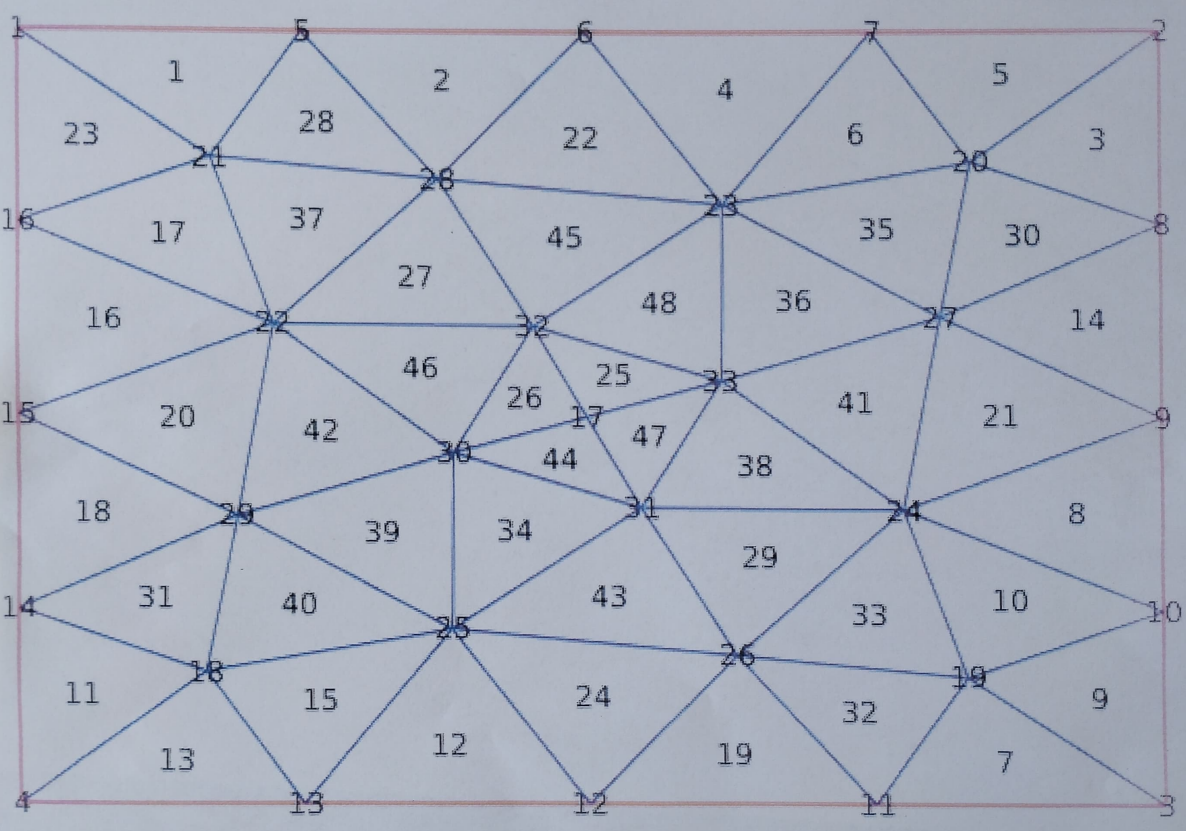 

Dans l'exemple de maillage présenté, si nous choisissons le triangle 39 par exemple, il aura les sommets 1, 2 et 3, correspondant aux sommets du maillage 29, 30 et 25. Si nous exécutons la matrice en tant que Num(39,30), elle renverra la valeur 2. De même, si nous exécutons Som(1,30), nous obtiendrons la coordonnée X du sommet 30. 

Taille caractéristique de la section

Echelle = 1; % En m à priori.

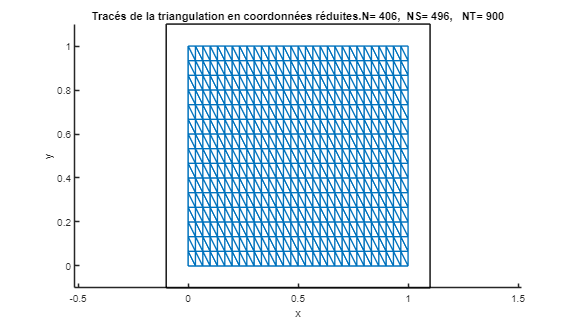

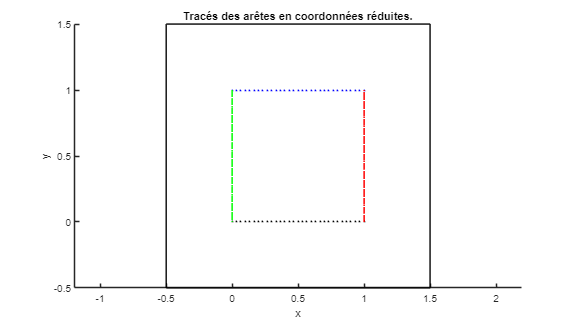

type = 0; % choisissant quelle type de maillage sera crée

switch type
    case {0} % Si "Mailleur_Simple_..."
        NomfichMaillage = 'triangulation_Rec'; % Nom du fichier de sauvegarde du maillage
        Longueur = Echelle; % En m à priori.
        Largeur = Longueur; % En m à priori.
        Nx = 30; % Entrée commune aux rectangles et aux triangles équilatéraux.
        Ny = 15; % Uniquement pour les rectangles
        Mailleur_Simple_Poiseuille_Rect(Longueur,Largeur,Echelle,Nx,Ny,NomfichMaillage);
    
    case{1}
        NomfichMaillage = 'triangulation_Tri';
        Longueur = Echelle; % En m à priori.
        Largeur = Longueur; % En m à priori.
        Nx = 30; % Entrée commune aux rectangles et aux triangles équilatéraux.
        Ny = 15; % Uniquement pour les rectangles
        Mailleur_Simple_Poiseuille_TriEqui(Longueur,Echelle,Nx,NomfichMaillage);
    
    case{2}
        % Si Conversion depuis freefem++
        % Le fichier ".msh" est réputé être en coordonnées réduites
        NomfichMaillage_freefem = 'Cacaouette_Avec_Trous.msh';
        NomfichMaillage = 'Cacaouette_Avec_Trous';
        Converti_Mailleur_Freefem(NomfichMaillage_freefem,NomfichMaillage,Echelle);
end

## Rechargement du fichier de maillage

% Nomfich = fichier contenant les données crées par le mailleur.
NomfichMaillage = strcat(NomfichMaillage,'.mat');
if (~exist(NomfichMaillage,'file'))
    error('Le maillage n"existe pas.');
end

% On charge le maillage et les diverses données utiles.
load(NomfichMaillage);

a = 1; % Chute de pression
mu = 1; % viscosité constante du modèle

## Tableau des matrices locales

% Initialisation/déclaration des cellules de "tab".
tab = cell(2,NT); 

for k = 1:NT
    tab{1,k} = 0.0; % surface du triangle
    tab{2,k} = zeros(3,3); % Matrice local K_loc
end

Obs : calcul et affectation dans "tab" des matrices locales, K_loc et des surfaces de chaque triangle.

## Aficher dans le tableau la surface des triangles du maillage et création du vecteur de solicitation et matrice de rigidité locale

Nous avons que l'aire A du triangle IJK est donée par :


$$2A = \left( \overrightarrow{IJ} \wedge  \overrightarrow{IK} \right)  \cdot \overrightarrow{z} = |(x_j - x_i)(y_k-y_i) - (x_k - x_i)(y_j-y_i)|$$


obs. : $\wedge \rightarrow$ conjunction operator (AND operator).

warning('off')
for k = 1:NT
    N1 = Num(1,k); % premier indice du noeud locale du triangle k
    N2 = Num(2,k);
    N3 = Num(3,k);
    
    x1 = Som(1,N1); % coordoné x du noeud N1 du triangle k
    x2 = Som(1,N2);
    x3 = Som(1,N3);
    
    y1 = Som(2,N1);
    y2 = Som(2,N2);
    y3 = Som(2,N3);
  
    % Aire du triangle 
    tab{1,k} = abs((x2-x1)*(y3-y1) -(x3-x1)*(y2-y1))/2;
    
    % Matrice de rigidité locale
    Kloc = zeros(3,3);

    Kloc(1,1) = ((x3-x2)^2 + (y3-y2)^2)/2;
    Kloc(2,2) = ((x3-x1)^2 + (y3-y1)^2)/2;
    Kloc(3,3) = ((x2-x1)^2 + (y2-y1)^2)/2;

    Kloc(1,2) = - ((x3-x1)*(x3-x2)) - ((y3-y1)*(y3-y2)) ;
    Kloc(1,3) = ((x2-x1)*(x3-x2)) + ((y2-y1)*(y3-y2)) ;
    Kloc(2,3) = - ((x2-x1)*(x3-x1)) - ((y2-y1)*(y3-y1));
    
    tab{2,k} = mu/(4*tab{1,k})*(Kloc+Kloc');
    
    % Vecteur de sollicitation local
    Floc = ones(3,1);
    Floc = a*tab{1,k}/3*Floc;
end

## Assemblage de la matrice de rigidité et du vecteur de sollicitation globaux

kglob = zeros(NS, NS);
Fglob = zeros(NS, 1);

for k = 1:NT
    mapp = Num(:,k);

    % ajoutant des valeurs des Klocs correspondants aux sommets
    for i = 1:3
        for j = 1:3
            kglob(mapp(i), mapp(j)) = kglob(mapp(i), mapp(j)) + tab{2,k}(i,j);
        end
    end

    % ajoutant des valeurs des Flocs correspondants aux bons sommets
    for i = 1:3
        Fglob(mapp(i)) = Fglob(mapp(i)) + Floc(i);
    end
end

## Conditions aux limites

Fglob(N + 1:NS) = zeros(NS - N, 1);
Kglob(N+1:NS, 1:N) = zeros(NS-N, N);
Kglob(N+1:NS, N+1:NS) = eye(NS-N);

## Calcul de la vitesse en résolvant le système linéaire  

Uglob = Kglob\Fglob;

## Affichage de la solution par "patches"

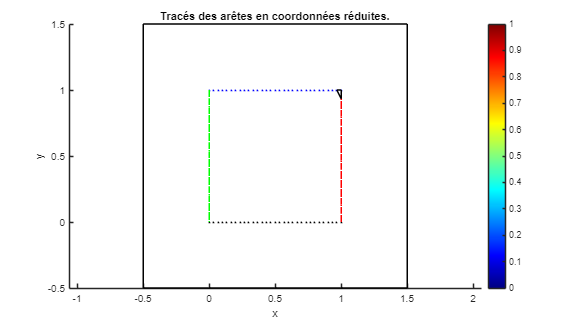

for i = 1:NT

    % coordonnés des sommets
    mapp = Num(:,k);
    
    x1 = Som(1,mapp(1));  
    x2 = Som(1,mapp(2));
    x3 = Som(1,mapp(3));
    
    y1 = Som(2,mapp(1));
    y2 = Som(2,mapp(2));
    y3 = Som(2,mapp(3));

    u1 = Uglob(mapp(1));
    u2 = Uglob(mapp(2));
    u3 = Uglob(mapp(3));

    % affichant le résultat
    patch([x1 x2 x3 x1], [y1 y2 y3 y1], [u1 u2 u3 u1]) 

end

colorbar 
axis equal
colormap('jet')

## Solution attendue et conclusion

Ci-dessous, nous avons le résultat attendu en appliquant la méthode étape par étape aux trois formes de maillage proposées. Nous constatons qu'au centre, l'écoulement est plus intense et qu'il le devient de moins en moins à mesure que l'on s'approche des bords du domaine. 

## 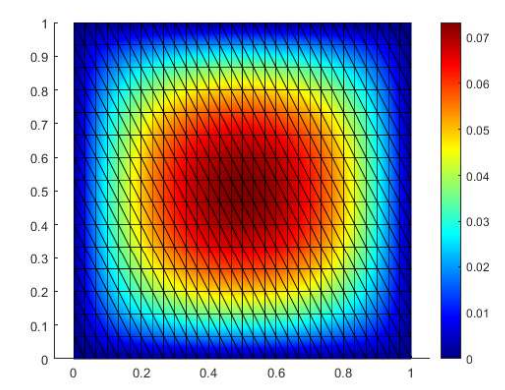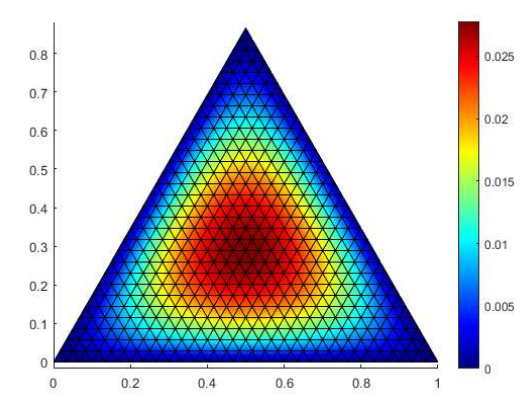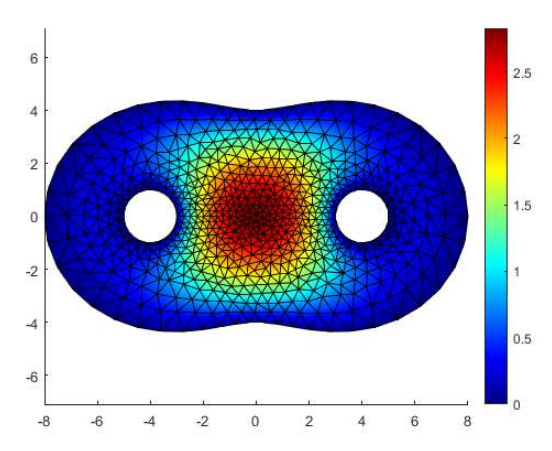

En conclusion, ce rapport présente l'application réussie de la méthode des éléments finis de type Pi/2D pour étudier l'écoulement de Poiseuille de liquides visqueux non newtoniens dans des conduites de section arbitraire. Trois maillages triangulaires différents ont été utilisés pour représenter les domaines carré, triangulaire et en forme de cacahuète. Cette méthode offre une approche numérique robuste et précise pour résoudre les problèmes de mécanique des fluides complexes, ouvrant ainsi de nouvelles perspectives pour la modélisation et l'analyse des écoulements réels dans des systèmes de conduites. L'utilisation de maillages triangulaires de formes variées a permis de modéliser des géométries de conduites réelles, allant des sections simples aux formes complexes. Cela démontre la flexibilité et l'adaptabilité de la méthode des éléments finis de type Pi/2D pour traiter des problèmes dans des configurations géométriques diverses.